## Parameters Setting:

addpath('main');
clear;
fact1=200;
% Number of pixels
Nu=684; 
Nv=944;  
du=40/Nu;  % pixel size
dv=du;

Np=100; % No. of projections from (0,2*pi)


u_cent=Nu/2; 
v_cent=Nv/2;

fact2=100;

%% Number of voxel
Nx=250;
Ny=250;
Nz=128;

%% Center of the phantom in Nx*Ny*Nz volume geometry
x_cent=Nx/2; 
y_cent=Ny/2;
z_cent=Nz/2;

%% Voxel size of phantom
dx=20/Nx;
dy=20/Nx;
dz=20/Nz;

### Getting phantom Features:

feat =shepp_logan(true);
%feat = ye_yu_wang()

## Constructing and visualizing Phantom:

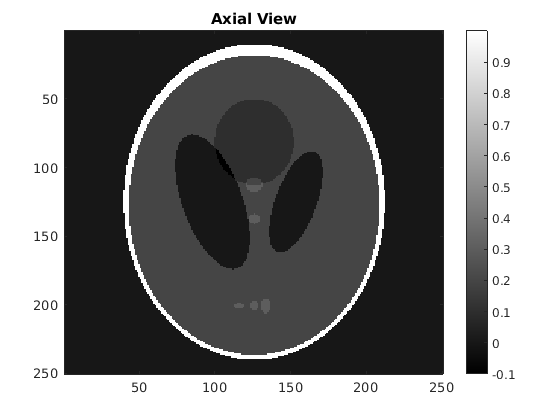


phantom  = phantom(x_cent,y_cent,z_cent,dx,dy,dz,Nx,Ny,Nz,feat);

%%-------------------------------------------------------------
imagesc(flipud((phantom(:,:,z_cent))),[min(phantom,[],"all") max(phantom,[],"all")]);
colormap gray;
title("Axial View");
colorbar;

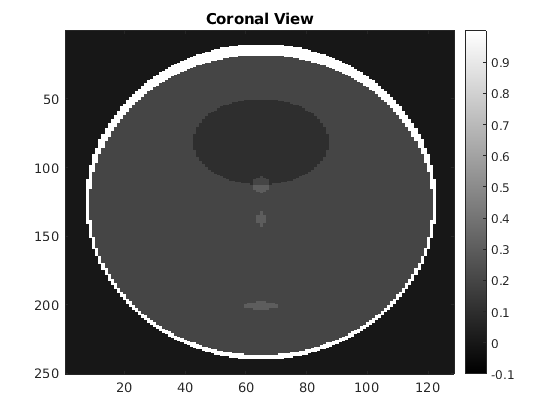

%%-------------------------------------------------------------
imagesc(flipud(squeeze(phantom(:,y_cent,:))),[min(phantom,[],"all") max(phantom,[],"all")])
colormap gray;
title("Coronal View");
colorbar;

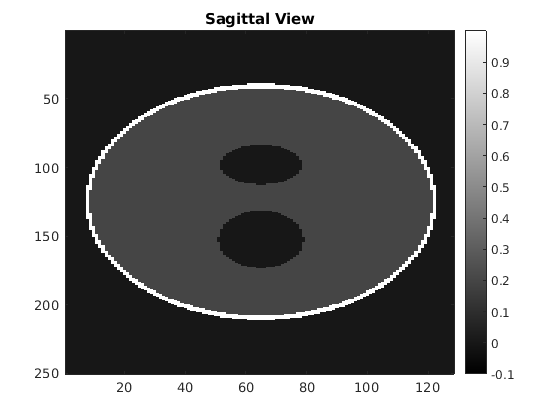

%%-------------------------------------------------------------
imagesc(flipud(squeeze(phantom(x_cent,:,:))),[min(phantom,[],"all") max(phantom,[],"all")])
colormap gray;
title("Sagittal View");
colorbar;
volumeViewer(phantom)

%clear phantom; %% Memory management

### Getting Projection data:

tic_ = tic;
%%-------------------------------------------------------------
proj  = projections(u_cent,v_cent,du,dv,Nu,Nv,Np,fact2,fact1,feat);
display("Time taken to get " + Np + " Projections: " + toc(tic_)+ "s");

    "Time taken to get 100 Projections: 104.043s"


%%-------------------------------------------------------------
clear feat tic_;

### Reconstructing the Projection data using FDK algorithm;

start = tic;
filter_image = back_project(proj, u_cent, v_cent, du, dv, fact2, fact1, x_cent, y_cent, ...
    z_cent, dx, dy, dz, Nx, Ny, Nz);
display("Time taken for reconstruction "+ toc(start)/60 + "min");

    "Time taken for reconstruction 3.9415min"


%%-------------------------------------------------------------
clear proj start;

#### Visualizing the backprojection data:

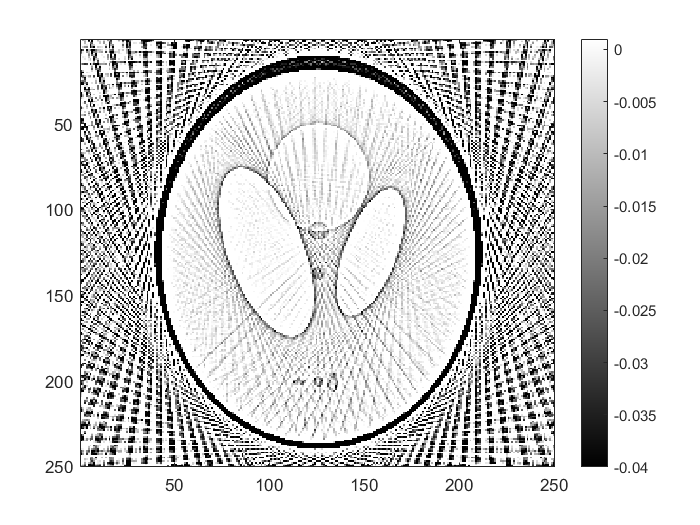

imagesc(flipud(del2(squeeze(filter_image(:,:,z_cent)))),[-0.04 0.001]);
colormap gray;
colorbar

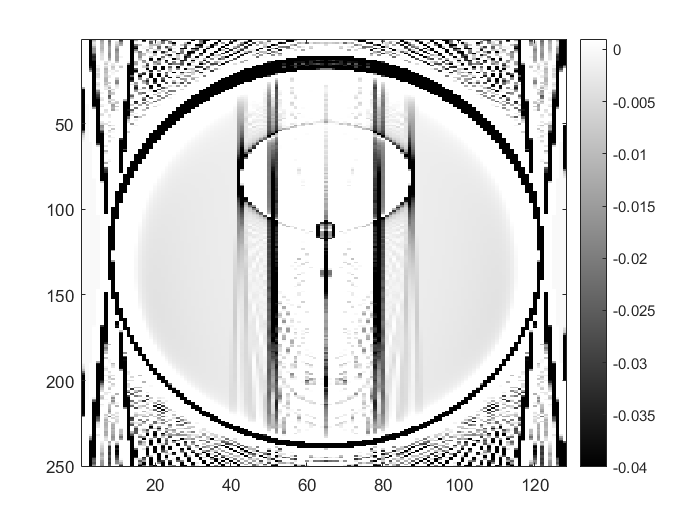

%%-------------------------------------------------------------
imagesc(flipud(del2(squeeze(filter_image(:,y_cent,:)))),[-0.04 0.001]);
colormap gray;
colorbar

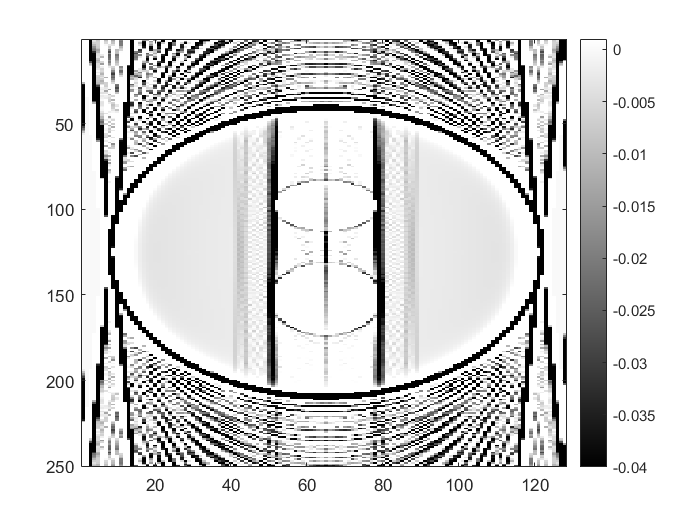

%%-------------------------------------------------------------
imagesc(flipud(del2(squeeze(filter_image(x_cent,:,:)))),[-0.04 0.001]);
colormap gray;
colorbar